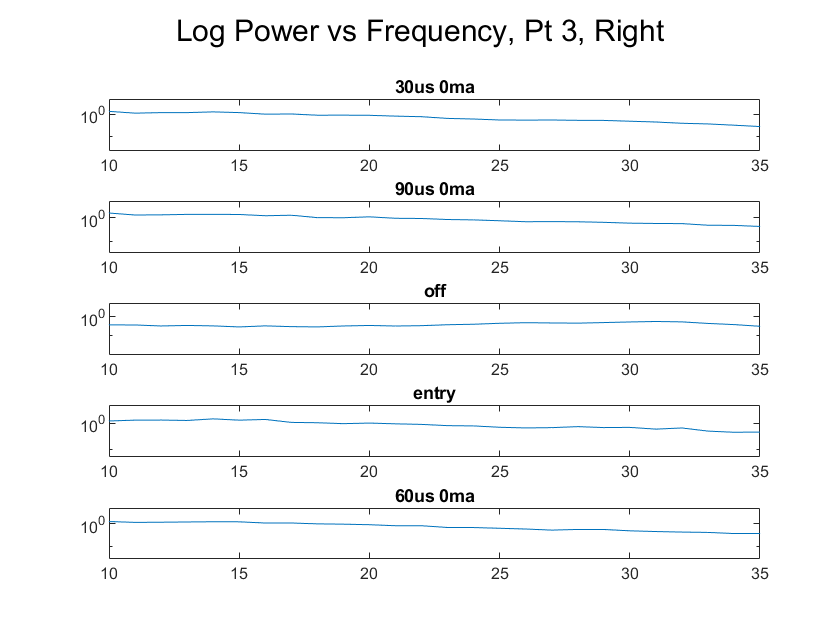

clear all;
figure;
%get the json 
cd('C:\Users\sydne\Documents\github\perceive\patientData\Patient4_0819')
jsonFiles = 'Report_Json_Session_Report_20210819T151123.json'; 
js = jsondecode(fileread(jsonFiles));
%set back to the correct directory 
cd('C:\Users\sydne\Documents\github\perceive\postAnalysis') 
%% create a struct of the relevant data from brainsense 
leng = numel(js.BrainSenseLfp);
data = struct;
for i=1:leng
    x = num2str(i);
    field = append("treatment", x);
    data.(field).channel = js.BrainSenseLfp(i).Channel;
    data.(field).time = datetime(replace({js.BrainSenseLfp(i).FirstPacketDateTime}, {'T', 'Z'},  {' ', ''}));
    data.(field).pw = js.BrainSenseLfp(i).TherapySnapshot.Right.PulseWidthInMicroSecond;
    data.(field).ma = js.BrainSenseLfp(i).TherapySnapshot.Right.LowerLimitInMilliAmps;
    data.(field).timeDomain = js.BrainSenseTimeDomain(i).TimeDomainData;
end 

%get legend info 
%some parts must be hard coded bc 
for i = 1:leng 
    x = num2str(i);
    field = append("treatment", x);
    pw = num2str(data.(field).pw); 
    ma = num2str(data.(field).ma);
    legendVal{i} = ((append(pw, "us ", ma, "ma")));
end 
legendVal{3} = "off";
legendVal{4} = "entry";

%% do pwelch on the LFP recording
%uncomment the subplot lines to just create a 5x1 subplot 
fs=250;
nfft=250;
window=250;
overlap=150;
subplot(leng, 1, 1)
for i=1:leng
    %make i usable for indexing into the struct 
    x = num2str(i);
    field = append("treatment", x);
    %calculate values
    t = data.(field).timeDomain;
    [pxx,f] = pwelch(t,window,overlap,nfft,fs);
    data.(field).LFPpower = pxx;
    data.(field).freq = f;
    fbeta = f > 12 & f < 33; 
    data.(field).avg = mean(pxx(fbeta));
    
    subplot(leng, 1, i)
    semilogy(f,sqrt(pxx))
    xlim([10 35])
    ylim([0 5])
    title(legendVal{i})
    hold on
end
sgtitle(["Log Power vs Frequency, Pt 3, Right"])



for i = 1:leng 
    x = num2str(i);
    field = append("treatment", x);
    means(i) = data.(field).avg;
end 

Tmean = array2table(means', 'VariableNames', {'Average Power in Beta Region (mV)'});
Tname = cell2table(legendVal', 'VariableNames', {'Treatment'}); 
tbl = [Tname Tmean];
sortrows(tbl, {'Average Power in Beta Region (mV)'}, 'descend')

ans = 5×2 table
    Treatment     Average Power in Beta Region (mV)
    __________    _________________________________

    "90us 0ma"                  0.9467             
    "entry"                    0.90118             
    "60us 0ma"                 0.72888             
    "30us 0ma"                 0.67262             
    "off"                      0.16494             


Because the data struct is odd and not showing the correct parameters, we look at raw data to see if that can give us any clues. 

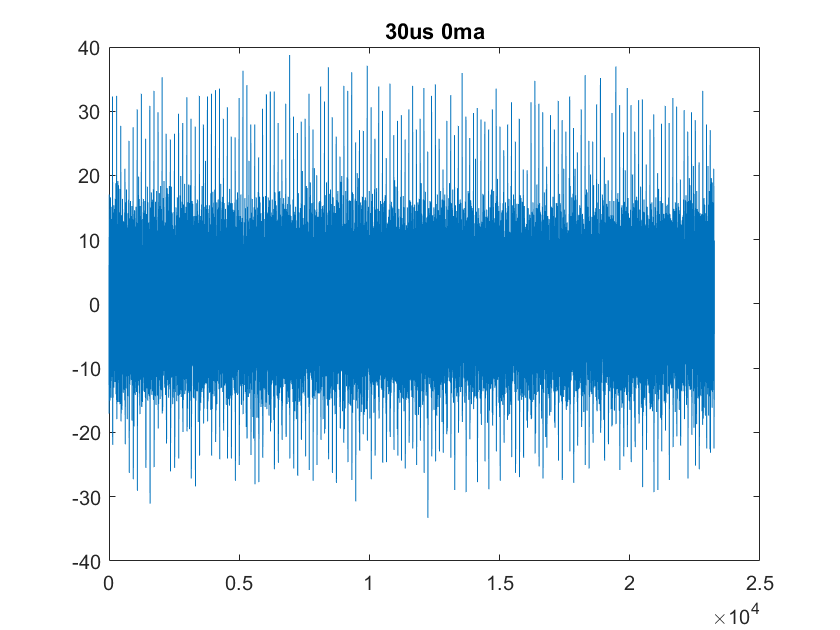

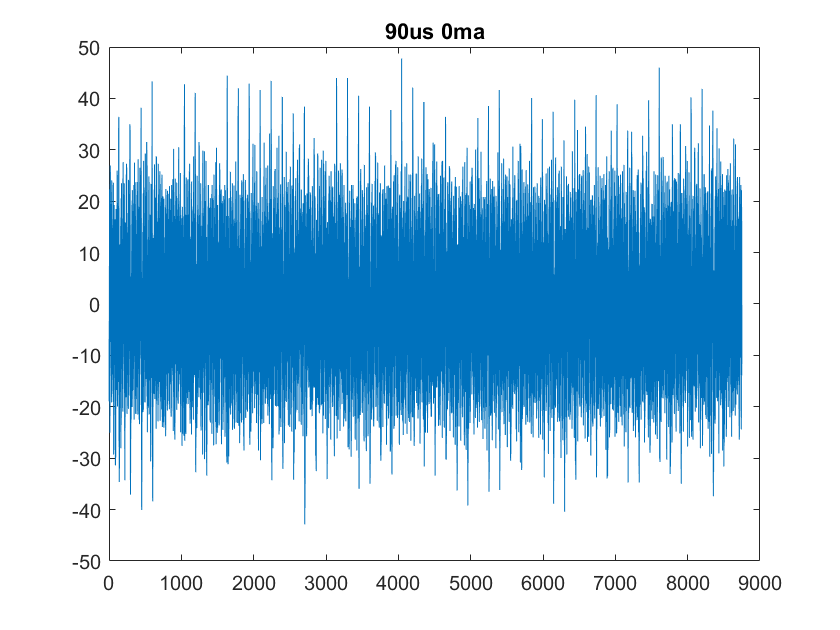

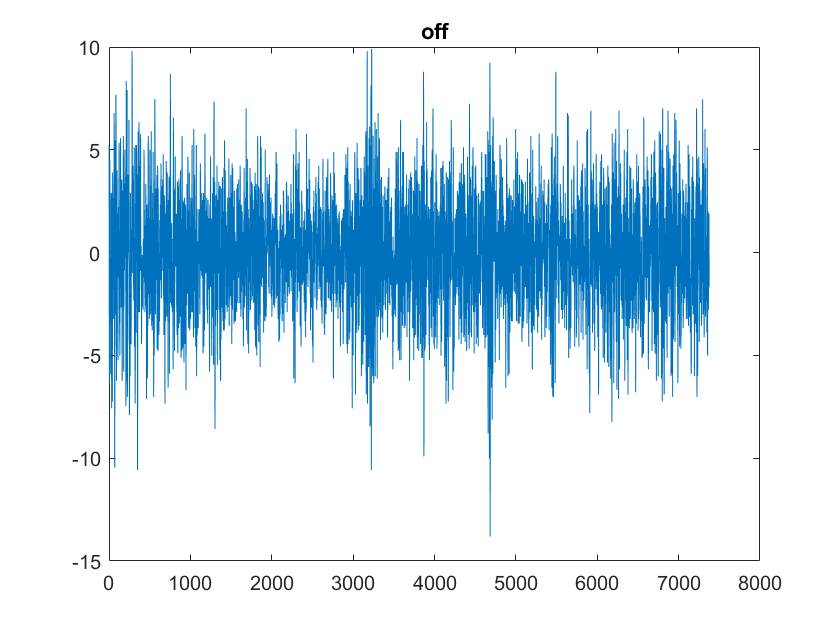

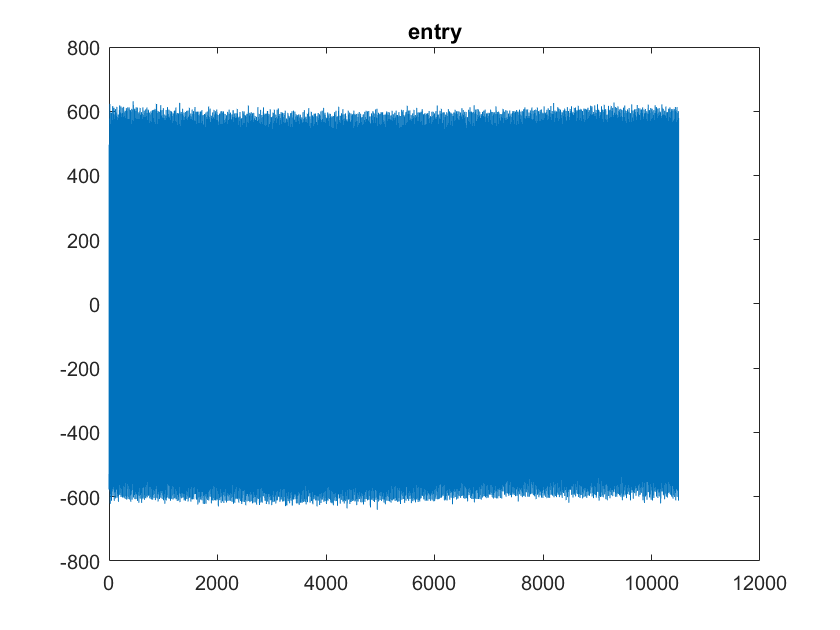

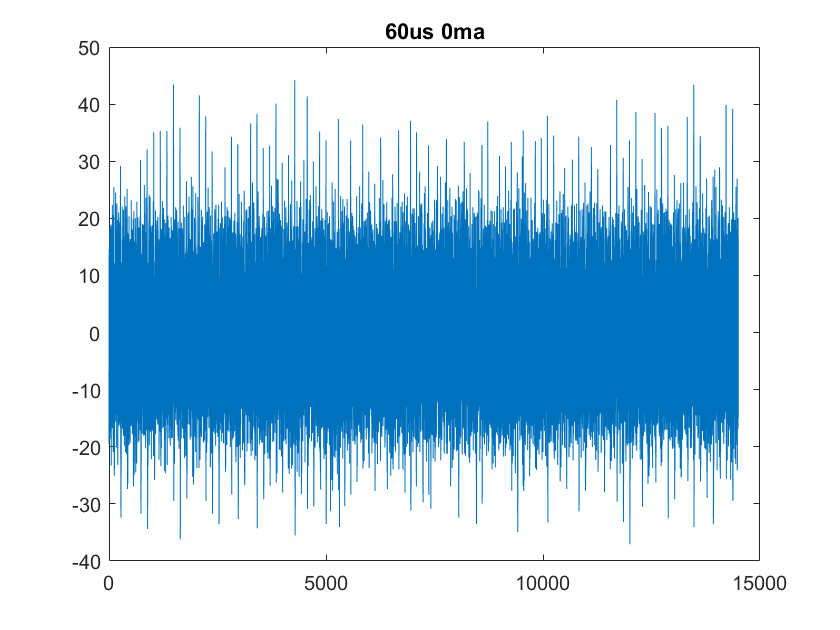

for i = 1:leng
    figure
    field = append("treatment", num2str(i));
    plot(data.(field).timeDomain) 
    title(legendVal{i})
end 